# radial profiles of HI and H2

## load important things

%loadFofSub

## load HI H2 values by components

load('C:\Users\eladz\Documents\workProjects\matlab_scripts\IllustrisTNG\matFiles\hih2Catalog_snp99_TNG100.mat')


## build stellar mass - HI mass relationship

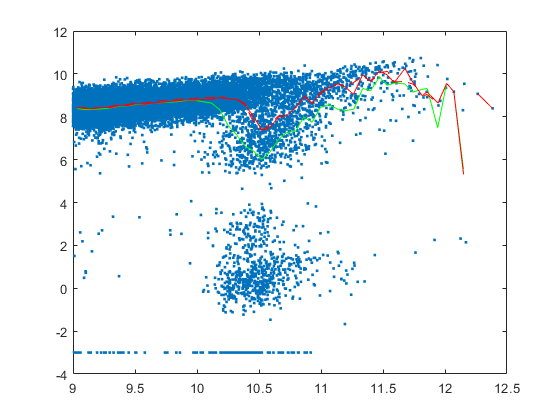


mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0;
galH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalHIMass(1,mmask)),'nb',50);

mmask=hih2Struct.galMask & hih2Struct.Gal.GalHIMass(1,:)>0 & subsInfo.isCentral;
galH_starC=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.Gal.GalHIMass(1,mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.Gal.GalHIMass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
plot(log10(smass),log10(hMass),'.');
hold on;
plot(galH_star.xMean,galH_star.yMean,'g')
plot(galH_star.xMedian,galH_star.yMedian,'r')
plot(galH_starC.xMedian,galH_starC.yMedian,'r--')

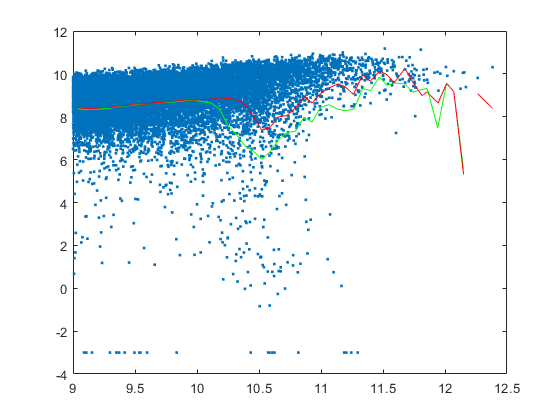




mmask=hih2Struct.galMask & hih2Struct.CGMall.CGMallHIMass(1,:)>0;
cgmH_star=mk_meanMedian_bin(log10(hih2Struct.galMass(mmask)),...
    log10(hih2Struct.CGMall.CGMallHIMass(1,mmask)),'nb',50);

figure
smass=hih2Struct.galMass(hih2Struct.galMask);
hMass=hih2Struct.CGMall.CGMallHIMass(1,hih2Struct.galMask);
hMass(hMass==0)=1e-3;
plot(log10(smass),log10(hMass),'.');
hold on;
plot(cgmH_star.xMean,star_h.yMean,'g')
plot(cgmH_star.xMedian,star_h.yMedian,'r')

## arrange profiles

hprofs=generate_hih2_profiles_3d(hih2Struct,fofs,subs,'mask',satMask,'mean200','bins',0.1:0.3:2.2);

## perliminaries


colors=brewermap(8,'Set1');
cind=[2 5 3 1];
htag={'11-12','12-13','13-14','14-15'};
mtag={'9-10','10-11','11-12'};

## plot by host mass

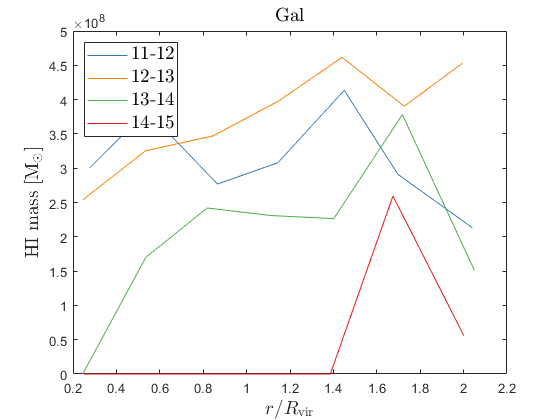


figure
h=[];

for j=1:4
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassMed(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass $[\mathrm{M_\odot}]$');
titlemine('Gal');

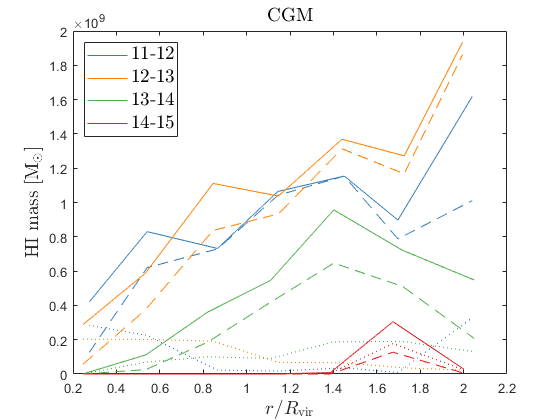


figure
h=[];

for j=1:4
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMed(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
    'color',colors(cind(j),:),'DisplayName',htag{j});

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
    'color',colors(cind(j),:),'DisplayName',htag{j});


end

legend(h(1:3:12),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass $[\mathrm{M_\odot}]$');
titlemine('CGM');

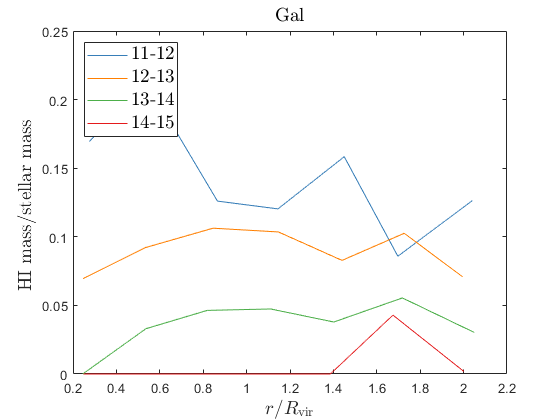


% normalized

figure
h=[];

for j=1:4
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassMedN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass/stellar mass ');
titlemine('Gal');

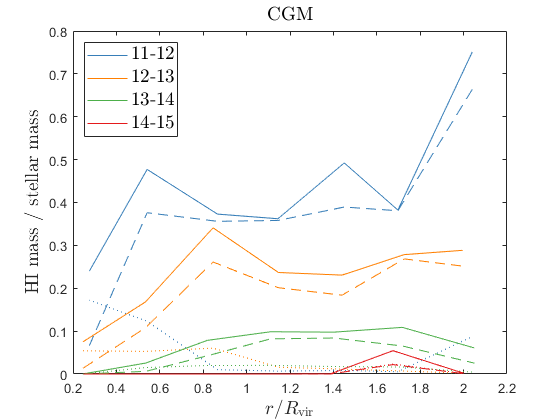


figure
h=[];

for j=1:4
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMedN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMedN(1,:,j),'--',...
    'color',colors(cind(j),:),'DisplayName',htag{j});

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMedN(1,:,j),':',...
    'color',colors(cind(j),:),'DisplayName',htag{j});


end

legend(h(1:3:12),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass / stellar mass');
titlemine('CGM');

## plot offset by host

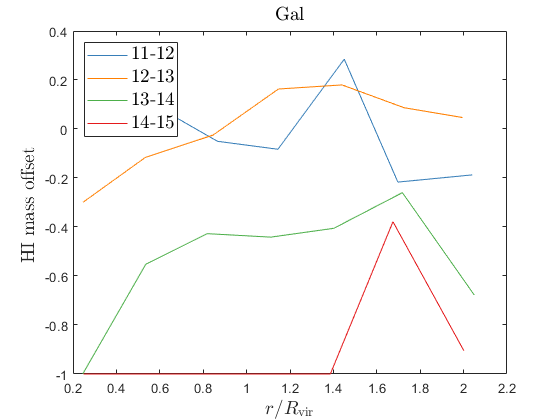


figure
h=[];

for j=1:4
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.Gal.hiMassMedDN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end
% h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.Gal.hiMassAvgDN(1,:,j),'--',...
%     'color',colors(cind(j),:),'DisplayName',htag{j});
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('Gal');

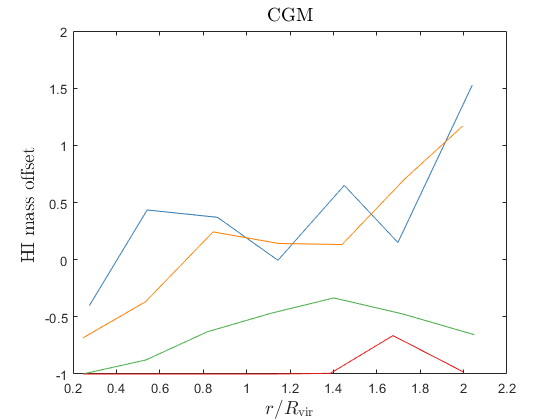


figure
h=[];

for j=1:4
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMall.hiMassMedDN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end
% h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byHost.CGMall.hiMassAvgDN(1,:,j),'--',...
%     'color',colors(cind(j),:),'DisplayName',htag{j});

% h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
%     'color',colors(cind(j),:),'DisplayName',htag{j});
% 
% h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
%     'color',colors(cind(j),:),'DisplayName',htag{j});


end
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('CGM');

## plot by stellar mass

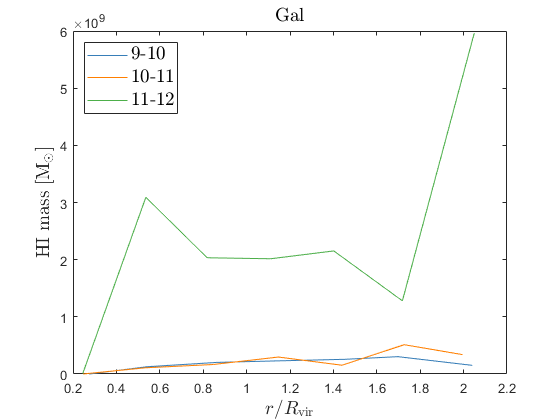

figure
h=[];

for j=1:3
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.Gal.hiMassMed(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',mtag{j});
if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass $[\mathrm{M_\odot}]$');
titlemine('Gal');

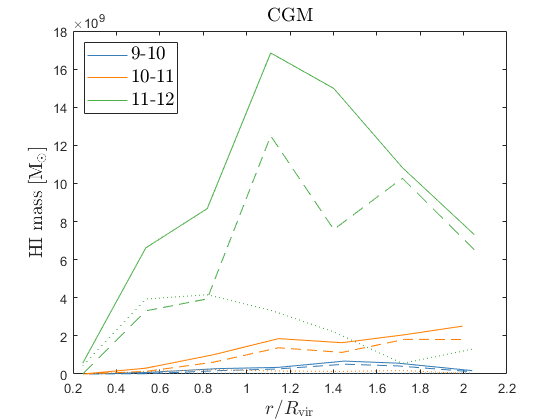


figure
h=[];

for j=1:3
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMall.hiMassMed(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',mtag{j});
if j==1;hold on;end

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMin.hiMassMed(1,:,j),'--',...
    'color',colors(cind(j),:),'DisplayName',mtag{j});

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMout.hiMassMed(1,:,j),':',...
    'color',colors(cind(j),:),'DisplayName',mtag{j});


end

legend(h(1:3:9),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass $[\mathrm{M_\odot}]$');
titlemine('CGM');

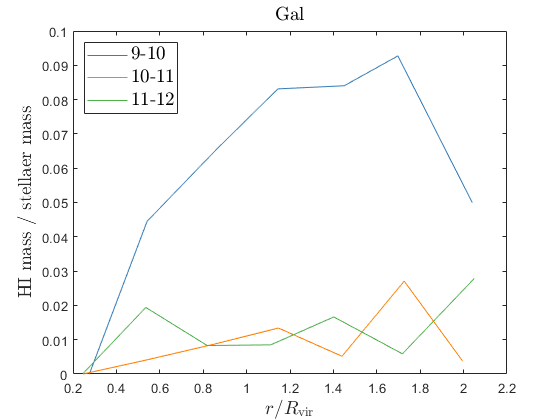


% normalized

figure
h=[];

for j=1:3
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.Gal.hiMassMedN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',mtag{j});
if j==1;hold on;end
end

legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass / stellaer mass');
titlemine('Gal');

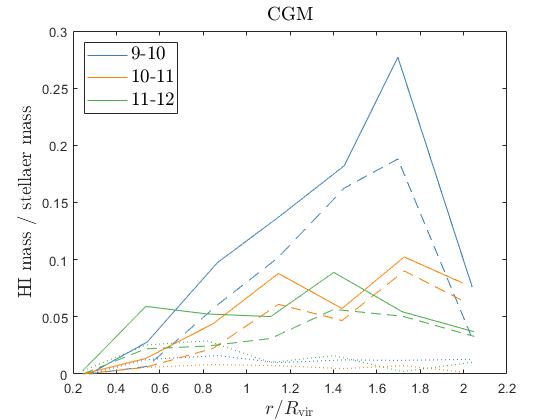


figure
h=[];

for j=1:3
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMall.hiMassMedN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',mtag{j});
if j==1;hold on;end

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMin.hiMassMedN(1,:,j),'--',...
    'color',colors(cind(j),:),'DisplayName',mtag{j});

h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMout.hiMassMedN(1,:,j),':',...
    'color',colors(cind(j),:),'DisplayName',mtag{j});


end

legend(h(1:3:9),'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass / stellaer mass');
titlemine('CGM');

## plot offset by mass


figure
h=[];

for j=1:3
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.Gal.hiMassMedN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end
h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byMass.Gal.hiMassAvgD(1,:,j),'--',...
    'color',colors(cind(j),:),'DisplayName',htag{j});
end

Reference to non-existent field 'hiMassMedDN'.


legend(h,'fontsize',14,'location','northwest','interpreter','latex');
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('Gal');

figure
h=[];

for j=1:3
h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byMass.CGMall.hiMassMedDN(1,:,j),...
    'color',colors(cind(j),:),'DisplayName',htag{j});
if j==1;hold on;end
h(end+1)=plot(hprofs.byHost.xAvg(:,j),hprofs.byMass.CGMall.hiMassAvgDN(1,:,j),'--',...
    'color',colors(cind(j),:),'DisplayName',htag{j});

% h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMin.hiMassMed(1,:,j),'--',...
%     'color',colors(cind(j),:),'DisplayName',htag{j});
% 
% h(end+1)=plot(hprofs.byHost.xMed(:,j),hprofs.byHost.CGMout.hiMassMed(1,:,j),':',...
%     'color',colors(cind(j),:),'DisplayName',htag{j});


end
xlabelmine('$r/R_\mathrm{vir}$');
ylabelmine('HI mass offset ');
titlemine('CGM');